# Compile Figures for Upper Kuparuk River Basin, Alaska

%%%%%%
%Script for compiling the figure generator
%%%%%%

clear all
close all


%What is your project name?
ProjFolder = 'figures/';

%What is the original data?
originaldata = {'UK_synthesized_data.txt'};

%do you want the figure saved?
printfig  = true;

%Where do you want to save files?
workdirfigures = '~/Documents/GitHub/Permafrost_ERRA/datERRA/UK_years/';

%Where is your data?
workdir = '~/Documents/GitHub/Permafrost_ERRA/datERRA/UK_years/Rresults';




%Set directories
workdirfig_ = {workdirfigures, ProjFolder};
workdirfig=char(strcat(workdirfig_(1),workdirfig_(2)));
if ~exist(workdirfig, 'dir')
    cd(workdirfigures)
    mkdir(ProjFolder)
end
cd(workdir)

Lets plot the results

I know the units of Q, what should the units of P be? Rainfall is at units of mm, but is that per second? The ReadMe file says precipitation is recorded hourly and nothing more. The data file says units of [mm] recorded every hour, so is it per hour? Also it says its resolution is 0.1 mm per tip. What does per tip mean?

Catchment Size of Upper Kuparuk Basin at Gauge Site is 142km^2.

From Kane:

"2007 was a relatively dry year, although all three years were below the average rainfall (222 mm). The main storage mechanism for the Upper Kuparuk is the active layer. While positive storage followed immediately after snowmelt, relative storage went from positive to negative during the summer and remained negative for the remainder of the summer as ET + Q exceeded P. The timing of this transition was later for those years with greater rainfall. Note that a large tundra wildfire in 2007 northwest of the Upper Kuparuk burned from early summer into early winter, and was the largest documented fire on the North Slope of Alaska. 

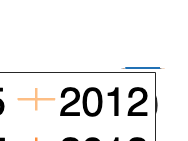





% prepare formating options
HA = {'HorizontalAlignment','left','center','right'};
VA = {'VerticalAlignment','bottom','middle','top'};
UN = {'Units','Normalized','Inches'};
TX = {'Interpreter','Latex'};
TL = {'TickLabelInterpreter','Latex'};

LW = {'LineWidth',1,1.25,1.5,2*2};
FS = {'FontSize',10*3,15*2,18*2,21*3,30*3};
MS = {'MarkerSize',6,8,12};
LS = {'LineStyle','-','--','-.',':'};
% LC = {'Color',color};
Colors = [203,201,226;
158,154,200;
106,81,163;
186,228,179;
116,196,118;
35,139,69;
253,190,133;
253,141,60;
217,71,1;
189,215,231;
107,174,214;
33,113,181
28,144,153]./255;

%Plotting profiles
axh = 5;
axw = 1.5*axh;
ahs = 0.8;
avs = 0.15;
axb = 0.7;
axt = 0.5;
axl = 1.0;
axr = 0.5;
cbh = axh; cbw = 0.2; ht = 0.05;
fh = axb + 1*axh + 1*avs + 1*ht + axt ;
fw = axl  + axw + ahs + cbw + axr;


% %set figure page
f1 = figure;

years = [2005 2007:2017];
maxRRD = zeros(size(years));
maxRRDlgt = zeros(size(years));
% RRD = zeros(numel(years),2000);
% se  = zeros(numel(years),2000);
% lagt = zeros(numel(years),2000);

%state the range of lag time to consider
hourrange = [0 30];
hourlimit = 0;


for jj = 1:numel(years) 
str = {'1hr_simple_',mat2str(years(jj)),'_RRD.txt'};
filename=char(strcat(str(1),str(2),str(3)));
[maxRRD(jj),maxRRDlgt(jj),maxRRDse(jj),RRD(:,jj),se(:,jj),lagt(:,jj)] = figtRRD_plot_years(filename,workdir,Colors(jj,:),hourlimit,hourrange);

end
if hourlimit
    xline(hourrange(1),'LineWidth',3,'Color',[0.65 0.85 0.90])
    xline(hourrange(2),'LineWidth',3,'Color',[0.65 0.85 0.90])
end

set(gca,'XLim',[min(min(lagt)),max(max(lagt))],'Ylim',[min(min([RRD-se])), max(max([RRD+se]))],TL{:},FS{[1,4]});

%set axis
xlabel('Hour lag',TX{:},FS{[1,4]},UN{[1,3]});
ylabel('Runoff Response Rate to Rainfall [1/hr]',TX{:},FS{[1,4]},UN{[1,3]});
legend(num2str(years.'), 'Location', 'northeast','NumColumns', 2);
%Save figure
if printfig
  cd(workdirfig);
  % set printing options
  str       = {'ltRRD' };
  format    = '-dpng';
  resl      = '-r200';
  rend      = '-opengl';
  figname   = char(strcat(str(1)));
  print(f1,format,resl,rend,figname,'-loose');
end

# Plot max RRD with each year

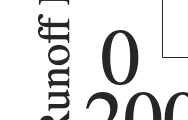

%set figure page
f2 = figure;
set(f2,'Units','Inches','Position',[0.7 12 fw fh]);
set(f2,'PaperPosition',[0 0 fw*2.2 fh*2.2],'PaperSize',[fw fh]);
set(f2,'Color','w','InvertHardcopy','off', 'MenuBar','none');
set(f2,'Resize','off','Toolbar','none');
ax = axes('Units','Inches','position',[axl+ahs axb axw axh]);
hold on
errorbar(years,maxRRD,maxRRDse,'.k','MarkerSize',45)
for jj = 1:numel(years)
    plot(years(jj),maxRRD(jj),'.','MarkerSize',45,'Color',Colors(jj,:))
end
set(gca,'XLim',[min(years),max(years)],'Ylim',[0, max(maxRRD+maxRRDse)],TL{:},FS{[1,5]});

%set axis
xlabel('Year',TX{:},FS{[1,4]},UN{[1,3]},'Position',[axw/2+ahs/2,-axb/2]);
ylabel('Peak Runoff Response Rate to Rainfall [1/hr]',TX{:},FS{[1,4]},UN{[1,3]},'Position',[-axl/2-ahs/2,axh/2]);
  

%Save figure
if printfig
  cd(workdirfig);
  % set printing options
  str       = {'maxRRD_year' };
  format    = '-dpng';
  resl      = '-r200';
  rend      = '-opengl';
  figname   = char(strcat(str(1)));
  print(f2,format,resl,rend,figname,'-loose');
end

# What parameters do we predict could be correlated with mRRD?

- Temperatures prior to summer -- confirmed

- Summer Temperatures -- confirmed

- Sum of Temperatures each day where T > 0 --confirmed

- Sum of Tempeartures each day --confirmed

- Peak April-June discharge -- confirmed

- Total snow thickness in winter -- confirmed

- Total Summer Precipitation -- done

- Total Summer Precipitation Year before

- Number of days with Precipitation in summer -- done

- Number of days with Precipitation Year before -- done

- Total Summer Rainfall -- done

- Total Summer Rainfall year before -- done

- Total number of days with rainfall in summer -- done

- Total number of days with rainfall in summer before -- done

- Average intensity of rainfall events

- Average intensity of rainfall event from summer before

- Rate of Thawing

precip = importdata("~/Documents/GitHub/Permafrost_ERRA/datERRA/archive/UK_thawingdepth_daily/precipitation.mat");
Precip = precip.P;
timedecyear = precip.short_t_cont_num;
Pyears = precip.years;
Pmonths = precip.months;
temp = importdata("~/Documents/GitHub/Permafrost_ERRA/datERRA/archive/UK_thawingdepth_daily/airtemperature.mat");
airtemp = temp.airtemp;
snowdepth = importdata("~/Documents/GitHub/Permafrost_ERRA/datERRA/archive/UK_thawingdepth_daily/snowdepth.mat");
SD = snowdepth.snowdepth;
discharge = importdata("~/Documents/GitHub/Permafrost_ERRA/datERRA/archive/UK_thawingdepth_daily/discharge.mat");
Q = discharge.Q;

%do daily averages of data
% Define the number of hours in a week
hours_per_day = 24;
% Reshape the data into a matrix with one week per column
num_days = floor(length(airtemp)/hours_per_day);
time_matrix = reshape(timedecyear(1:num_days*hours_per_day), hours_per_day, num_days);
months_matrix = reshape(Pmonths(1:num_days*hours_per_day), hours_per_day, num_days);
airtemp_matrix = reshape(airtemp(1:num_days*hours_per_day), hours_per_day, num_days);
precip_matrix = reshape(Precip(1:num_days*hours_per_day), hours_per_day, num_days);
discharge_matrix = reshape(Q(1:num_days*hours_per_day), hours_per_day, num_days);
SD_matrix = reshape(SD(1:num_days*hours_per_day), hours_per_day, num_days);



% Calculate the mean of each column to get the weekly averages
time_da = nanmean(time_matrix, 1);
months_da = floor(nanmean(months_matrix,1));
airtemp_da = nanmean(airtemp_matrix, 1);
save('~/Documents/GitHub/Permafrost_ERRA/datERRA/UK_thawingdepth_daily_2/airtemp.mat',"time_da","airtemp_da","months_da")
precip_da = nanmean(precip_matrix, 1).*24; %%precipitation per day
save('~/Documents/GitHub/Permafrost_ERRA/datERRA/UK_thawingdepth_daily_2/precipitation.mat',"time_da","precip_da","months_da")
Q_da = nanmean(discharge_matrix, 1).*24; %discharge per day
save('~/Documents/GitHub/Permafrost_ERRA/datERRA/UK_thawingdepth_daily_2/dischargedaily.mat',"time_da","Q_da","months_da")
SD_da = nanmax(SD_matrix);
year_time = floor(time_da);

logindxMonths = months_da >5 & months_da <9;
logindxMonthsJ = (months_da  <= 5 );
logindxMonthsApJ = (months_da  > 3 & months_da  < 7 );
logindxMonthsSep = (months_da  <=6);
logindxTgt0C  = airtemp_da > 0;
logindxTgt4C = airtemp_da >4;
RF_da = precip_da;
RF_da(~logindxTgt4C) = 0;
SF_da = precip_da;
SF_da(logindxTgt4C) = 0;

f1 = figure;

for l = 1: numel(years)

        logindxYears = year_time == years(l);
        logindxYears_Yrbfr = year_time == years(l)-1;

        totaldata(l) = sum(logindxYears);
        totalP(l) = nansum(precip_da(logindxYears));
        meanTJuly(l) = nanmean(airtemp_da(logindxYears & logindxMonthsJ)); %% 1. Temperature prior to summer
        TSummer(l) = nanmean(airtemp_da(logindxYears & logindxMonths)); %% 2. Summer Temperatures

        %adding temperatures over days

        CountTgt0(l) = nansum(airtemp_da(logindxYears & logindxTgt0C)); %% 3. Sum of Temperatures each day where T > 0
        CountTall(l) = nansum(airtemp_da(logindxYears)); %% 4. Sum of Temperatures each day 
        CountDaysTexist(l) = nansum(~isnan(airtemp_da(logindxYears))); % Make sure you have same number of days counted (some NAN values exist)
        CountDaysTexist_Summer(l) = nansum(~isnan(airtemp_da(logindxYears & logindxMonths))); % Make sure you have same number of days counted in Summer (some NAN values exist) 
        CountDaysT(l) = nansum(~isnan( airtemp_da(logindxYears & logindxTgt0C))); %Number of days where Temperature is >0
        CountDaysTlt0(l) = nansum(~isnan( airtemp_da(logindxYears & ~logindxTgt0C))); %Number of days where Temperature is <=0
        CountDaysTNAN(l) = nansum(isnan(airtemp_da(logindxYears)));

        Q_max_april_june(l) = nanmax(Q_da(logindxYears & logindxMonthsApJ)); %% 5. Peak discharge [mm/day]
        Q_Spring_Count(l) = sum(~isnan(Q_da(logindxYears & logindxMonthsApJ))); %% How many days in Spring do we have discharge data?
        Q_total_april_june(l) = nanmean(Q_da(logindxYears & logindxMonthsApJ)).*30*3; %% Total Spring Discharge
        P_total_april_june(l) = nanmean(precip_da(logindxYears & logindxMonthsApJ )).*30*3; %Total Spring Precipitation
 
        RF_total_april_june(l) = nanmean(RF_da(logindxYears & logindxMonthsApJ )).*30*3; %Total Spring Precipitation

        SD_max(l) = nanmax(SD_da(logindxYears & logindxMonthsJ)); %% 6. Max snow depth [cm but mostly NaN vallues]

        totalPSummer(l) = nanmean(precip_da(logindxYears & logindxMonths))*30*3; %% 7. Total Summer Precipitation
        totalPSummer_Yrbfr(l) = nanmean(precip_da(logindxYears_Yrbfr & logindxMonths))*30*3; %% 8. Total Summer Precipitation yearbefore
        totaldaysPgt0(l) = nansum(precip_da(logindxYears & logindxMonths)>0); %% 9. Total number of days when precipitation is greater than 0
        totaldaysPgt0_Yrbfr(l) = nansum(precip_da(logindxYears_Yrbfr & logindxMonths)>0); %% 10. Total number of days when precipitation is greater than 0 in year before
        totaldaysPlt0(l) = sum(precip_da(logindxYears & logindxMonths)<=0); %% Number of days when the precipitation is 0
        totaldaysPNAN(l) = sum(isnan(precip_da(logindxYears & logindxMonths))); %% Number of days when the precipitation is NAN

        totalRFSummer(l) = nanmean(RF_da(logindxYears & logindxMonths ))*30*3; %% 11. Total Summer Rainfall
        totalSFSummer(l) = nanmean(SF_da(logindxYears & logindxMonths ))*30*3; %% 11. Total Summer Rainfall

        totalRFSummer_Yrbf(l) = nanmean(RF_da(logindxYears_Yrbfr & logindxMonths ))*30*3; %% 12. Total Summer Rainfall
        totaldaysRFgt0(l) = sum(RF_da(logindxYears & logindxMonths )>0); %% 13. Total number of days when rainfall is greater than 0
        totaldaysRFlt0(l) = sum(RF_da(logindxYears & logindxMonths )<=0); %% Total number of days when rainfall is less than 0
        totaldaysRFNAN(l) = sum(isnan(RF_da(logindxYears & logindxMonths ))); %% Total number of days when rainfall is NaN
        
        totaldaysRFgt0_Yrbf(l) = nansum(RF_da(logindxYears_Yrbfr & logindxMonths )>0); %% 14. Total number of days when rainfall is greater than 0
        RF_intensity(l) = nansum(RF_da(logindxYears & logindxMonths ))./totaldaysRFgt0(l); %% 15. Average intensity of rainfall events
        RF_intensity_Yrbf(l) = nansum(RF_da(logindxYears_Yrbfr & logindxMonths ))./totaldaysRFgt0_Yrbf(l);  %% 16. Average intensity of rainfall events summer before

        totalT(l) = nanmean(airtemp(logindxYears)); 
        Q_year = Q(logindxYears);
        P_year = Precip(logindxYears);
        time = timedecyear(logindxYears);
end

%Rate of thawing
load('~/Documents/GitHub/Permafrost_ERRA/datERRA/UK_years/DepthAL_temperature.mat','cm_p_day','years_available')
rateofthawing = cm_p_day;
Poly_years = years_available;
for i = 1: numel(years)
    RThawing(i) = rateofthawing(years(i) == Poly_years);
end



% VarParameters = [meanTJuly; TSummer; CountTgt0; CountTall; Q_max_april_june; SD_max; ...
%     totalPSummer; totalPSummer_Yrbfr; totaldaysPgt0; totaldaysPgt0_Yrbfr;...
%     totalRFSummer; totalRFSummer_Yrbf; totaldaysRFgt0; totaldaysRFgt0_Yrbf; RF_intensity; RF_intensity_Yrbf];
% VarParameters_Names = {'Win $\&$ Sprg Temp [$^{\circ}$C]', 'Summer Temp [$^{\circ}$C]', 'Sum Temperature $> 0^{\circ}$C [$^{\circ}$C d]', 'Sum Temperature [$^{\circ}$C d]','Max Sprg Q [mm/d]','Max Ann Snow Thickness [cm]',...
%     'Total Summer P [mm/3mo]', 'Total Previous Summer P [mm/3mo]', 'Total P Days [days/3mo]', 'Tot P Yr Bfr [days/3mo]',...
%     'Total Summer Rainfall [mm/3mo]', 'Total Summer Rainfall [mm/3mo]', 'Total Rainfall Dys [days/3mo]', 'Total Rainfall Dys from Yr Bfr [days/3mo]',...
%     'Average Rainfall Intensity [mm/da]', 'Average Rainfall Intensity Prev. Summer [mm/da]'};
% cd('~/Documents/git_research/Permafrost_ERRA/Permafrost_ERRA/datERRA/UK_years/');
% save('Considered_VarParameters.mat',"VarParameters_Names","VarParameters","meanTJuly", "TSummer", "CountTgt0", "CountTall", "Q_max_april_june", "SD_max", ...
%     "totalPSummer", "totalPSummer_Yrbfr", "totaldaysPgt0","totaldaysPgt0_Yrbfr",...
%     "totalRFSummer", "totalRFSummer_Yrbf", "totaldaysRFgt0", "totaldaysRFgt0_Yrbf", "RF_intensity", "RF_intensity_Yrbf","years",...
%     "Q_total_april_june","P_total_april_june","RF_total_april_june","maxRRD")


VarParameters = [  totalPSummer; totalRFSummer;  RF_intensity;  meanTJuly;...
       RF_intensity_Yrbf; totalSFSummer; totalRFSummer_Yrbf; CountTgt0;  TSummer; Q_max_april_june; SD_max; RThawing];
VarParameters_Names = {'Total Summer Precip [mm/3 mo]', 'Total Summer Rainfall [mm/3 mo]', {'Average Rainfall', 'Intensity [mm/d]'}, 'Win $\&$ Sprg Temp [$^{\circ}$C]',{'Average Rainfall Intensity', 'Prev Summer [mm/d]'},'Total Snow Precip [mm/3 mo]',...
    {'Total Rainfall', 'Prev Summer [mm/3 mo]'}, ...
    'Sum Temperature $> 0^{\circ}$C [$^{\circ}$C d]','Summer Temp [$^{\circ}$C]', 'Max Sprg Q [mm/d]', 'Max Ann Snow Thickness [cm]', 'Rate of Thawing [cm/d]'};

VarParameters_txt = {'maxRRD'; 'totalPSummer'; 'totalRFSummer';  'RF_intensity';  'meanTJuly';...
       'RF_intensity_Yrbf'; 'totalSFSummer'; 'totalRFSummer_Yrbf'; 'CountTgt0';  'TSummer'; 'Q_max_april_june'; 'SD_max'; 'RThawing'};

% cd('~/Documents/git_research/Permafrost_ERRA/Permafrost_ERRA/datERRA/UK_years/');
% save('Considered_VarParameters.mat',"VarParameters_Names","VarParameters","meanTJuly", "TSummer", "CountTgt0", "CountTall", "Q_max_april_june", "SD_max", ...
%     "totalPSummer", "totalPSummer_Yrbfr", "totaldaysPgt0","totaldaysPgt0_Yrbfr",...
%     "totalRFSummer", "totalRFSummer_Yrbf", "totaldaysRFgt0", "totaldaysRFgt0_Yrbf", "RF_intensity", "RF_intensity_Yrbf","years",...
%     "Q_total_april_june","P_total_april_june","RF_total_april_june","RThawing","maxRRD")


[B, FitInfo] = lasso(VarParameters', maxRRD,'DFmax',2);
% Find the index of the lambda with the minimum MSE
    [~, idxLambdaBest] = min(FitInfo.MSE);  % This finds the index of the minimum MSE
    
    % Get the best model coefficients for that lambda
    B_best = B(:, idxLambdaBest);
    
    % Identify non-zero coefficients
    importantVarsIdx = find(B_best ~= 0);
    
    % Manually map the non-zero coefficients to the corresponding names in VarParameters_Names
    importantVars = VarParameters_Names(importantVarsIdx);

[rSquaredMatrix, bestPair, bestR2] = pairwise_r2(VarParameters', maxRRD)

Matrix of R-squared values for all pairwise combinations of predictors:
    0.3439    0.3475    0.3651    0.5782    0.3485    0.3473    0.3735    0.3565    0.3954    0.3719    0.9107    0.4808
    0.3475    0.3152    0.3308    0.4729    0.3152    0.3482    0.3203    0.3152    0.3302    0.3263    0.9957    0.5700
    0.3651    0.3308    0.2362    0.4462    0.2382    0.2441    0.2445    0.2363    0.2594    0.2548    0.9757    0.5827
    0.5782    0.4729    0.4462    0.1516    0.2117    0.2053    0.1520    0.2610    0.2287    0.1650    0.7653    0.6440
    0.3485    0.3152    0.2382    0.2117    0.0186    0.0212    0.1290    0.0186    0.0219    0.0215    0.8434    0.4972
    0.3473    0.3482    0.2441    0.2053    0.0212    0.0074    0.0240    0.0076    0.0115    0.0097    0.7651    0.7923
    0.3735    0.3203    0.2445    0.1520    0.1290    0.0240    0.0068    0.0102    0.0080    0.0074    0.7490    0.7095
    0.3565    0.3152    0.2363    0.2610    0.0186    0.0076    0.0102    0.0026 

rSquaredMatrix =     0.3439    0.3475    0.3651    0.5782    0.3485    0.3473    0.3735    0.3565    0.3954    0.3719    0.9107    0.4808
    0.3475    0.3152    0.3308    0.4729    0.3152    0.3482    0.3203    0.3152    0.3302    0.3263    0.9957    0.5700
    0.3651    0.3308    0.2362    0.4462    0.2382    0.2441    0.2445    0.2363    0.2594    0.2548    0.9757    0.5827
    0.5782    0.4729    0.4462    0.1516    0.2117    0.2053    0.1520    0.2610    0.2287    0.1650    0.7653    0.6440
    0.3485    0.3152    0.2382    0.2117    0.0186    0.0212    0.1290    0.0186    0.0219    0.0215    0.8434    0.4972
    0.3473    0.3482    0.2441    0.2053    0.0212    0.0074    0.0240    0.0076    0.0115    0.0097    0.7651    0.7923
    0.3735    0.3203    0.2445    0.1520    0.1290    0.0240    0.0068    0.0102    0.0080    0.0074    0.7490    0.7095
    0.3565    0.3152    0.2363    0.2610    0.0186    0.0076    0.0102    0.0026    0.0375    0.0027    0.7713    0.4944
    0.3954    0

bestPair =     12    11


bestR2 = 1

% 
% mdl_sglm = stepwiseglm(VarParameters',maxRRD','VarNames',VarParameters_txt,'PEnter',0.01)
% disp(mdl_sglm)

Test to confirm that Temperatures are correctly averaged. Confirmed

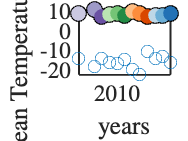


f1 = figure;
plot(years,meanTJuly,'o','MarkerSize',10)
hold on
yearsplots(years,TSummer,years,zeros(size(years)),'years','Mean Temperatures [$^{\circ}$C]','W $\&$ S T and Summer T',0,0)

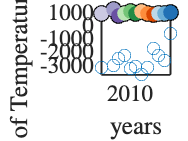


f1 = figure;
plot(years,CountTall,'o','MarkerSize',10)
hold on
yearsplots(years,CountTgt0,years,zeros(size(years)),'years','Sum of Temperatures [$^{\circ}$ C da]','T $>0^{\circ}$ and all T',0,0)

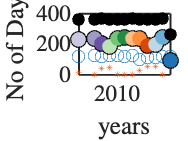


f1 = figure;
plot(years,CountDaysT,'o','MarkerSize',10)
hold on
plot(years,CountDaysTNAN,'*','MarkerSize',5)
yearsplots(years,CountDaysTlt0,years,zeros(size(years)),'years','No of Days','T $>0^{\circ}$ in o, T$<0^{\circ}$C in colors, and nan T in *',0,0)
plot(years, CountDaysT + CountDaysTNAN + CountDaysTlt0, 'k.','MarkerSize',30)

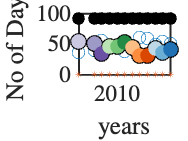


f1 = figure;
plot(years,totaldaysPgt0,'o','MarkerSize',10)
hold on
plot(years,totaldaysPNAN,'*','MarkerSize',5)
yearsplots(years,totaldaysPlt0,years,zeros(size(years)),'years','No of Days','P $>0$mm/day in o, P$=0$mm/day in colors, and nan P in *',0,0)
plot(years, totaldaysPgt0 + totaldaysPNAN + totaldaysPlt0, 'k.','MarkerSize',30)

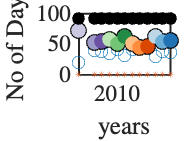


f1 = figure;
plot(years,totaldaysRFgt0,'o','MarkerSize',10)
hold on
plot(years,totaldaysRFNAN,'*','MarkerSize',5)
yearsplots(years,totaldaysRFlt0,years,zeros(size(years)),'years','No of Days','RF $=0$mm/day in o, RF$<0$mm/day in colors, and nan RF in *',0,0)
plot(years, totaldaysRFgt0 + totaldaysRFNAN + totaldaysRFlt0, 'k.','MarkerSize',30)

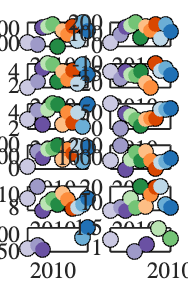

%Plotting profiles
axh = 8;
axw = .5*axh;
ahs = 0.8;
avs = 0.15;
axb = .0;%1.5;
axt = 1.;%1.5;
axl = 0.50;
axr = 0.5;
cbh = axh; cbw = 0.2; ht = 0.05;
fh = axb + 1*axh + 1*avs + 1*ht + axt ;
fw = axl  + axw + ahs + cbw + axr;

f1 = figure;
set(f1,'Units','Inches','Position',[0.7 12 fw fh]);
set(f1,'PaperPosition',[0 0 fw*2.2 fh*2.2],'PaperSize',[fw fh]);
set(f1,'Color','w','InvertHardcopy','off', 'MenuBar','none');
set(f1,'Resize','off','Toolbar','none');
ax = axes('Units','Inches','position',[axl+ahs axb axw axh]);

for l = 1:numel(VarParameters(:,1))
    subplot(6,2,l)

    yearsplots(years,VarParameters(l,:),years,zeros(size(years)),'','',VarParameters_Names{l},0,0)
    if l ==11
        yearsplots(years,VarParameters(l,:),years,zeros(size(years)),'Year','',VarParameters_Names{l},0,0)
    end
end
if printfig
  cd(workdirfig);
  % set printing options
  str       = {'Explanatory_years' };
  format    = '-dpng';
  resl      = '-r200';
  rend      = '-opengl';
  figname   = char(strcat(str(1)));
  print(f1,format,resl,rend,figname,'-loose');
end

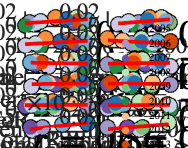

%% Set up figure dimensions
axh = 5; axw = axh;
ahs = 0.15; avs = 0.15;
axb = 1.5; axt = 0.9; axl = 1.7; axr = 1.1;
cbh = axh; cbw = 0.2; ht = 0.05;
fh = axb + axh + avs + ht + axt;
fw = axl + axw + ahs + cbw + axr;

%% Create and configure the main figure
f1 = figure;
set(f1, ...
  'Units','Inches',      'Position',[0.7 12 fw fh], ...
  'PaperPosition',[0 0 fw*2.2 fh*2.2], 'PaperSize',[fw fh], ...
  'Color','w',           'InvertHardcopy','off', ...
  'MenuBar','none',      'Resize','off',        'Toolbar','none');

%% Number of predictors
nVars = size(VarParameters,1);

%% Loop through each predictor and plot vs. maxRRD
for l = 1:nVars
    subplot(6,2,l)
    hold on 
    
    % Fit linear model
    mdl2 = fitlm( VarParameters(l,:), maxRRD, 'linear' );
    
    % Compute Pearson r = sign(slope)*sqrt(R2)
    slope_sign = sign( mdl2.Coefficients.Estimate(2) );
    R2          = mdl2.Rsquared.Ordinary;
    r_val       = slope_sign * sqrt( R2 );
    r_val       = round( r_val*100 )/100;  % two decimals
    
    % Plot data + errorbars + fit via your helper
    yearsplots(VarParameters(l,:),maxRRD,years,maxRRDse,VarParameters_Names{l},'','',0,1)
    yl = ylim;                    
    set(gca, 'YLim', [yl(1), yl(2)*1.5]);
    % Ensure hold is on for the text
    hold on
    
    % Add correlation coefficient inside the plot
    text(0.05, 0.95, sprintf('$r=%.2f$', r_val), 'Units','normalized', ...
      'HorizontalAlignment','left', ...
      'VerticalAlignment','top', ...
      TX{:}, FS{[1,3]});
    
    hold off
end

%% 1) Optionally widen the figure so there’s space
figPos = get(f1,'Position'); 
% add 1.5 inches of width for the legend
set(f1,'Position',[figPos(1), figPos(2), figPos(3)+1.5, figPos(4)]);
set(f1,'PaperSize',[figPos(3)+1.5, figPos(4)]);

%% 2) Define your years and matching colors
years = [2005, 2006, 2007:2017];          % make sure this is length N
Colors = [ ...
  203,201,226; 158,154,200; 106,81,163; ...
  186,228,179; 116,196,118; 35,139,69;   ...
  253,190,133; 253,141,60;  217,71,1;    ...
  189,215,231; 107,174,214; 33,113,181; 28,144,153 ] / 255;

%% 3) Create an invisible axes on the right
legAx = axes( ...
  'Units','normalized', ...
  'Position',[0.92, 0.10, 0.05, 0.80], ...  % [x y w h] in norm. units
  'Visible','off' );

%% 4) Plot one dummy scatter per year in that axes
hold(legAx,'on');
hLeg = gobjects(numel(years),1);
for k = 1:numel(years)
  hLeg(k) = scatter( ...
    legAx, NaN, NaN, ...                   % no real data
    50, Colors(k,:), 'filled' );
end
hold(legAx,'off');

%% 5) Turn those dummy handles into a legend
lgYears = legend( ...
  legAx, hLeg, arrayfun(@num2str,years,'UniformOutput',false), ...
  TX{:}, 'Box','off');

%% Optionally save the figure
if printfig
    cd(workdirfig);
    print(f1, '-dpng', '-r400', '-opengl', 'SingleLRM', '-loose');
end

% Set up figure size
fw = 8;  % width in inches
fh = 12; % height in inches

% Create figure
f1 = figure;
set(f1, 'Units', 'Inches', 'Position', [0.7, 12, fw, fh]);
set(f1, 'PaperPosition', [0, 0, fw * 2.2, fh * 2.2], ...
        'PaperSize', [fw, fh]);
set(f1, 'Color', 'w', 'InvertHardcopy', 'off', ...
        'MenuBar', 'none', 'Resize', 'off', 'Toolbar', 'none');

% Plot loop
for l = 1:numel(VarParameters(:,1))
    subplot(6, 2, l);  % Create a 6x2 grid of subplots

    % Fit linear model
    mdl2 = fitlm(VarParameters(l,:), maxRRD, 'linear');
    rsqrd2 = round(100 * mdl2.Rsquared.Ordinary) / 100;
    ttle = sprintf('R$^2$ %.2f', rsqrd2);

    % Call your plotting function
    yearsplots(VarParameters(l,:), maxRRD, years, maxRRDse, ...
               VarParameters_Names{l}, '', ttle, 0, 1);

    % Add y-label to subplot #9
    if l == 5
        yearsplots(VarParameters(l,:), maxRRD, years, maxRRDse, ...
                   VarParameters_Names{l}, 'Peak Runoff Response [1/hr]', ...
                   ttle, 0, 1);
    end
end

% Print figure if flag is set
if printfig
    cd(workdirfig);
    str     = {'SingleLRM'};
    format  = '-dpng';
    resl    = '-r400';
    rend    = '-opengl';
    figname = char(str(1));
    print(f1, format, resl, rend, figname, '-loose');
end


WinterTemp = meanTJuly; Precipitation = totalPSummer; Snowmelt = Q_max_april_june; mRRD = maxRRD;
% T = table(WinterTemp',  Precipitation', Snowmelt', mRRD', 'VariableNames', {'WinterTemp', 'Precipitation','Snowmelt', 'mRRD'});
T = table(WinterTemp', Precipitation', mRRD', 'VariableNames', {'WinterTemp', 'Precipitation', 'mRRD'});

% Create the linear regression model
mdl = fitlm(T, 'mRRD ~ WinterTemp  + Precipitation ');

% Display the model coefficients
disp(mdl.Coefficients);

% Display the R-squared value
disp(mdl.Rsquared.Adjusted);


A = mdl.Coefficients.Estimate("WinterTemp");
B = mdl.Coefficients.Estimate("Precipitation");
% C = mdl.Coefficients.Estimate("Snowmelt");
D = mdl.Coefficients.Estimate("(Intercept)");
% RHS = A.*WinterTemp + B.*Precipitation + C.*Snowmelt + D;
% RHS = A.*WinterTemp + C.*Snowmelt  + D;
RHS = A.*WinterTemp + B.*Precipitation  + D;

f1 = figure;
 set(f1,'Units','Inches','Position',[0.7 12 fw fh]);
 set(f1,'PaperPosition',[0 0 fw*2.2 fh*2.2],'PaperSize',[fw fh]);
 set(f1,'Color','w','InvertHardcopy','off', 'MenuBar','none');
 set(f1,'Resize','off','Toolbar','none');
 ax = axes('Units','Inches','position',[axl axb+axt/2 axw axh]);

yearsplots(RHS,mRRD,years,maxRRDse,'Fitted Value from Model [1/hr]','Peak Runoff Response Rate [1/hr]','',1,0);

plot([0 .015],[0 .015],'-k','LineWidth',2)
axis equal
axis square

if printfig
  cd(workdirfig);
  % set printing options
  str       = {'ModelFit' };
  format    = '-dpng';
  resl      = '-r400';
  rend      = '-opengl';
  figname   = char(strcat(str(1)));
  print(f1,format,resl,rend,figname,'-loose');
end

fig1 = figure;

yearsplots(Precipitation,WinterTemp,years,zeros(size(years)),'Total Annual Precipitation [mm/3mo]','Average W $\&$ S T [$^{\circ}$ C]','',1,0);
if printfig
  cd(workdirfig);
  % set printing options
  str       = {'PrecipWinter' };
  format    = '-dpng';
  resl      = '-r200';
  rend      = '-opengl';
  figname   = char(strcat(str(1)));
  print(fig1,format,resl,rend,figname,'-loose');
end

fig1 = figure;

load('~/Documents/GitHub/Permafrost_ERRA/datERRA/UK_years/deltaT_winterspring.mat','years_available','AV_dT_dt')
 rateofthawing = AV_dT_dt;
Poly_years = years_available;
for i = 1: numel(years)
    WinterDT(i) = rateofthawing(years(i) == Poly_years);
end

yearsplots(WinterTemp,WinterDT,years,zeros(size(years)),'Average W $\&$ S T [$^{\circ}$ C]','Temperature Change in Spring [$^{\circ}$C / 7days]','',1,0);
if printfig
  cd(workdirfig);
  % set printing options
  str       = {'WinterdTdt' };
  format    = '-dpng';
  resl      = '-r200';
  rend      = '-opengl';
  figname   = char(strcat(str(1)));
  print(fig1,format,resl,rend,figname,'-loose');
end


fig1 = figure;

yearsplots(WinterTemp,RThawing,years,zeros(size(years)),'Average W $\&$ S T [$^{\circ}$ C]','Thawing Rate [cm/d]','',1,0);
if printfig
  cd(workdirfig);
  % set printing options
  str       = {'WinterRoThawing' };
  format    = '-dpng';
  resl      = '-r200';
  rend      = '-opengl';
  figname   = char(strcat(str(1)));
  print(fig1,format,resl,rend,figname,'-loose');
end

WinterTemp = zscore(meanTJuly); Precipitation = zscore(totalPSummer); Snowmelt = zscore(Q_max_april_june); [mRRD, muRRD, stdRRD] = zscore(maxRRD);
% T = table(WinterTemp',  Precipitation', Snowmelt', mRRD', 'VariableNames', {'WinterTemp', 'Precipitation','Snowmelt', 'mRRD'});
T = table(WinterTemp', Precipitation', mRRD', 'VariableNames', {'WinterTemp', 'Precipitation', 'mRRD'});
erzscore = maxRRDse / stdRRD;
% Create the linear regression model
mdl = fitlm(T, 'mRRD ~ WinterTemp  + Precipitation ');

% Display the model coefficients
disp(mdl.Coefficients);

% Display the R-squared value
disp(mdl.Rsquared.Adjusted);


A = mdl.Coefficients.Estimate("WinterTemp");
B = mdl.Coefficients.Estimate("Precipitation");
% C = mdl.Coefficients.Estimate("Snowmelt");
D = mdl.Coefficients.Estimate("(Intercept)");
% RHS = A.*WinterTemp + B.*Precipitation + C.*Snowmelt + D;
% RHS = A.*WinterTemp + C.*Snowmelt  + D;
RHS = A.*WinterTemp + B.*Precipitation  + D;
figure; 
errorbar(RHS,mRRD,erzscore,'.k','MarkerSize',45*2)
hold on
yearsplots(RHS,mRRD,years,[],'Fitted Value from Model','Peak Runoff Response Rate','',1,0);
hold on

%%%% How do you add variability on zscores?
plot([-2 2],[-2 2],'-k','LineWidth',2)
set(gca,'XLim',[-2,2],'Ylim',[-2,2],TL{:},FS{[1,4]});
axis square
% axis equal


if printfig
  cd(workdirfig);
  % set printing options
  str       = {'FitModel' };
  format    = '-dpng';
  resl      = '-r400';
  rend      = '-opengl';
  figname   = char(strcat(str(1)));
  print(f1,format,resl,rend,figname,'-loose');
end


% %%%% Testing out making leverage plots using jmp method. 
f2 = figure;
plotAdded(mdl,"WinterTemp")
xlabel('Adjusted Winter $\&$ Spring Temp',TX{:},FS{[1,5]},UN{[1,3]})
ylabel('Adjusted Peak Runoff Response ',TX{:},FS{[1,5]},UN{[1,3]})
title('Added Variables Plot',TX{:},FS{[1,4]},UN{[1,3]})
set(gca,TL{:},FS{[1,5]});

if printfig
  cd(workdirfig);
  % set printing options
  str       = {'AddedVarPlot_WT' };
  format    = '-dpng';
  resl      = '-r200';
  rend      = '-opengl';
  figname   = char(strcat(str(1)));
  print(f2,format,resl,rend,figname,'-loose');
end

f2 = figure;
plotAdded(mdl,"Precipitation")
set(gca,TL{:},FS{[1,5]});
xlabel('Adjusted Summer Precipitation ',TX{:},FS{[1,5]},UN{[1,3]})
ylabel('Adjusted Peak Runoff Response ',TX{:},FS{[1,5]},UN{[1,3]})
title('Added Variables Plot',TX{:},FS{[1,4]},UN{[1,3]})
set(gca,TL{:},FS{[1,5]});

if printfig
  cd(workdirfig);
  % set printing options
  str       = {'AddedVarPlot_Precip' };
  format    = '-dpng';
  resl      = '-r200';
  rend      = '-opengl';
  figname   = char(strcat(str(1)));
  print(f2,format,resl,rend,figname,'-loose');
end


## Save files to txt

% %First make a table
% WinterTemp = totalTJuly'; 
% Precipitation = totalP'; 
% mRRD = maxRRD';
% zWinterTemp = zscore(totalTJuly)'; 
% zPrecipitation = zscore(totalP)'; 
% zmRRD = zscore(maxRRD)';
% years = years';
% Mtxt = table(years,WinterTemp,Precipitation,mRRD,...
%     zWinterTemp,zPrecipitation,zmRRD);
% writetable(Mtxt,'ModelParams','WriteRowNames',true,'Delimiter',',');
%     TDat = [WinterTemp,Precipitation,mRRD];